**GROUP 2 - ASSIGNMENT 3 SUBMISSION:**

- Claudio Demaria - s5433737

- Enrico Piacenti - s5636699

- Gianluca Galvagni - s5521188

- Manuel Delucchi - s4803977

## REACHING TASK

In this task, our goal was to move a cursor within the VR toolbox screen by using the Cartesian position of the Phantom Robot's end effector. The objective was to reach eight targets distributed randomly across a circular area displayed on the screen.

The initial state of the StateFlow block diagram involves shuffling the positions of the eight targets to ensure that each target is plotted and subsequently reached at least once during the simulation.

Upon reaching and plotting 10 targets, the simulation stops automatically.

Reaching

Since the 'Phantom Simulink block' only works if connected to the real robot, we have created an alternative simulation where it is possible to modify the position of the cursor using sliders (one for the x axis and one for the y axis). This adaptation enables testing and validation of the program's functionality even in the absence of a physical connection to the robot.

Reaching_test

## FORCE FIELD

In this task, our objective was to define two distinct force fields for the robot's end effector. The first field functions as an attraction force guiding the end effector towards a specified target, while the second field acts as a viscous force opposing the end effector's velocity.

The attractive force field, proportional to the end effector's position, tries to draw the end effector towards a predefined home position (set to [0,0,0]). Note that the field's nature can be changed from attractive to repulsive simply by modifying the sign of the gain value that scales the end effector's position.

The forces calculated using the end effector's position and velocity are multiplied with the transpose of the Jacobian of the Phantom robot that is calculated inside the 'Omni_jacobian_Transpose' matlab function.

It's important to note that all parameters used in the simulations have been tailored to suit the 'Geomagic Touch - Phantom Omni' robot showed in the picture below.

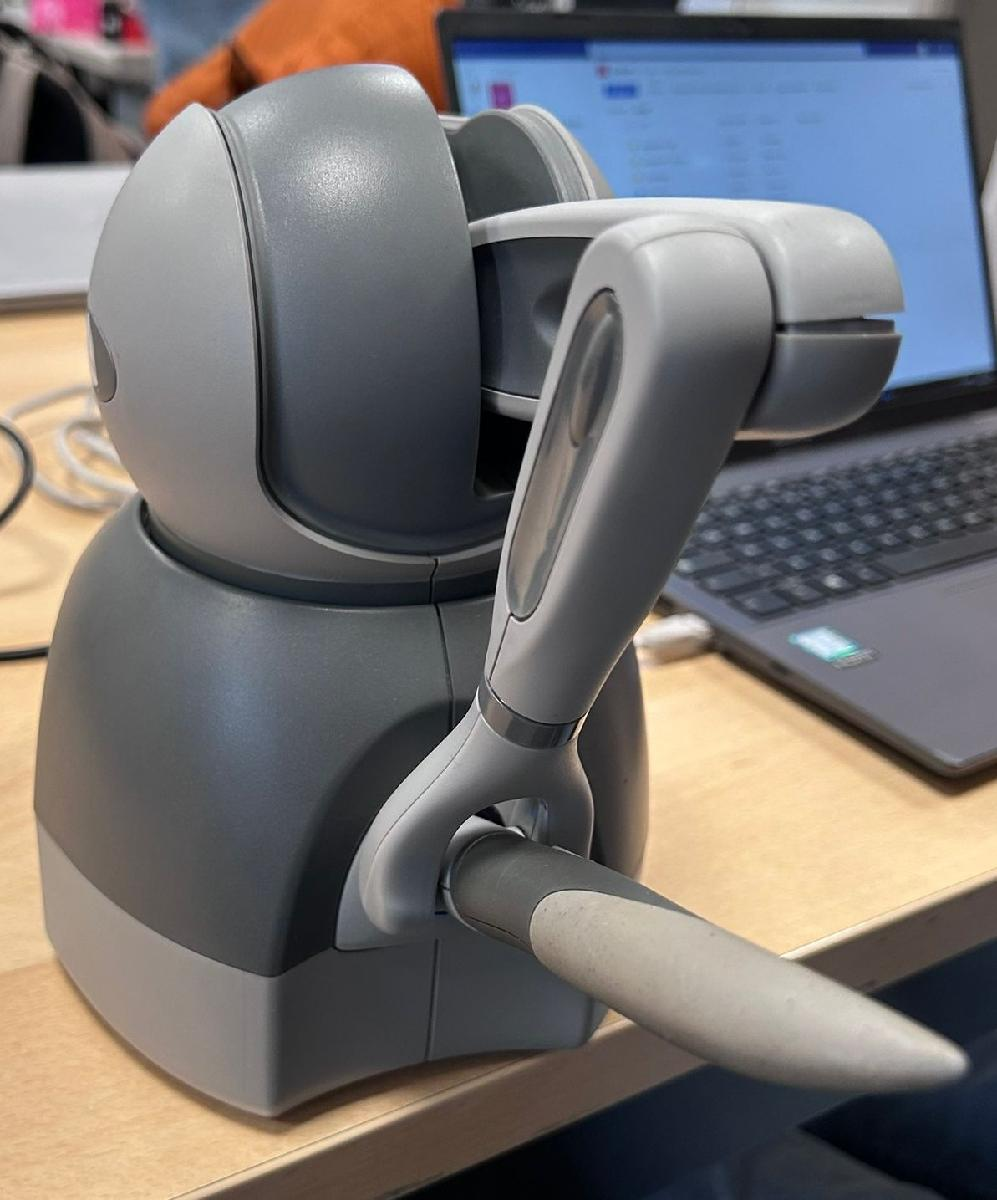

ForceField_wBlocks

## FORCE FIELD - REACHING TASK

In this final task, we combined the two exercises we have shown before to reach eight targets on the screen. This was achieved by applying two force fields as torque input to the robot.

To execute this, we used the 'Geomagic Touch X' as depicted in the image below. It's important to note that the gains associated with the two force fields applied were specifically tailored for this robot and might not be compatible with the 'Geomagic Touch - Phantom Omni' robot.

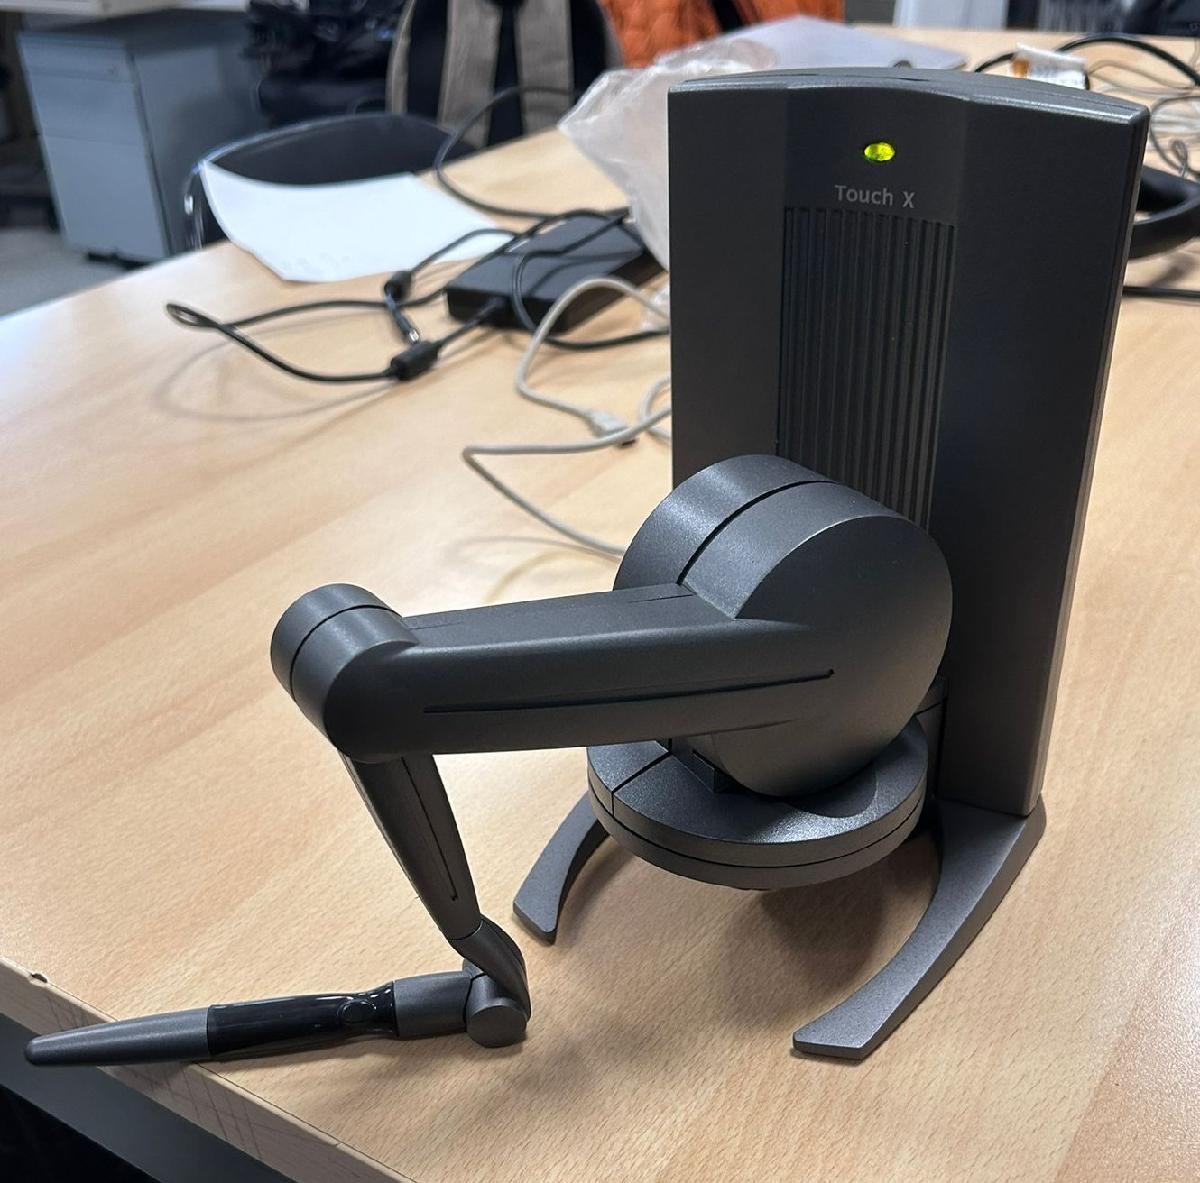

ForceField_Reaching